LMS Part D Code

hbar=1.06e-34; %Plancks constant [Js]
q=1.6e-19; %Elementary charge [C]
eps0=8.85e-12; %Permitivity of free space [F/m]
epsr=12.5; %Relative permittivity
m=0.067*9.1e-31; %Effective mass [kg]
k=8.617e-5; %Boltzmann constant [eV/K]

`% Calculation parameters (Change as neccessary) `

a=3e-11; %mesh size [m] (Default is 30 pm)
mu=1   ; %Chemical potential [eV]
T=293    ; %Temperature [K]
Nout=100   ; %Outer passivating layer
Nin=66   ; %Inner passivating layer-seperates the two wells
Nw1=100   ; %First (left) well
Nw2=100   ; %Second (right) well
E_m=0.33 ;
E_out=0.33;
Vg=0; %Gate potential (not used for this calculation)

`% Parameters needed for calculations. Do not change.`

t0=(hbar^2)/(2*m*(a^2)*q); %Scaling factor
e0=q*a/eps0; %Scaling factor
kT=k*T; 
n0=m*kT*q/(2*pi*(hbar^2)); %2D DOS
Np=2*Nout+Nin+Nw1+Nw2; %layer thickness in units of mesh size

`% Matrices needed for setting up calculation.`

XX=a*1e9*[1:1:Np]; %Position in nm
Ec=[E_out*ones(Nout,1);0*ones(Nw1,1);E_m*ones(Nin,1);0*ones(Nw2,1);E_out*ones(Nout,1)]; %Conduction band position
T=(2*t0*diag(ones(1,Np)))-(t0*diag(ones(1,Np-1),1))-(t0*diag(ones(1,Np-1),-1)); 
D2=epsr*((2*diag(ones(1,Np)))-(diag(ones(1,Np-1),1))-diag(ones(1,Np-1),-1));
iD2=inv(D2);
Ubdy=-4*[Vg;zeros(Np-2,1);Vg]; 
U0=iD2*Ubdy;
U1=1e-9*ones(Np,1);UU=U1;change=1;
while change>1e-6
    U1=U1+0.1*(UU-U1);
    [P,D]=eig(T+diag(Ec)+diag(U1));D=diag(D);
    rho=log(1+exp((mu-D)./kT)); rho=P*diag(rho)*P';
    n=2*n0*diag(rho);
    UU=U0+iD2*e0*n;
    change=max(max((abs(UU-U1))));
    U=Ec+U1;
    disp(change)
end;

    2.1446

    1.2997

    0.8286

    0.5361

    0.3515

    0.2338

    0.1572

    0.1073

    0.0745

    0.0524

    0.0374

    0.0270

    0.0198

    0.0147

    0.0111

    0.0085

    0.0066

    0.0052

    0.0041

    0.0033

    0.0027

    0.0023

    0.0019

    0.0016

    0.0013

    0.0013

    0.0011

    0.0010

   9.4338e-04

   8.4898e-04

   7.6128e-04

   6.8073e-04

   6.0738e-04

   5.4102e-04

   4.8126e-04

   4.2765e-04

   3.7970e-04

   3.3691e-04

   2.9880e-04

   2.6489e-04

   2.3476e-04

   2.0801e-04

   1.8427e-04

   1.6322e-04

   1.4456e-04

   1.2803e-04

   1.1338e-04

   1.0041e-04

   8.8920e-05

   7.8745e-05

   6.9735e-05

   6.1757e-05

   5.4693e-05

   4.8439e-05

   4.2901e-05

   3.7998e-05

   3.3656e-05

   2.9812e-05

   2.6408e-05

   2.3394e-05

   2.0725e-05

   1.8361e-05

   1.6267e-05

   1.4413e-05

   1.2771e-05

   1.1317e-05

   1.0029e-05

   8.8874e-06

   7.8765e-06

   6.9809e-06

   6.1874e-06

   5.4845e-06

   4

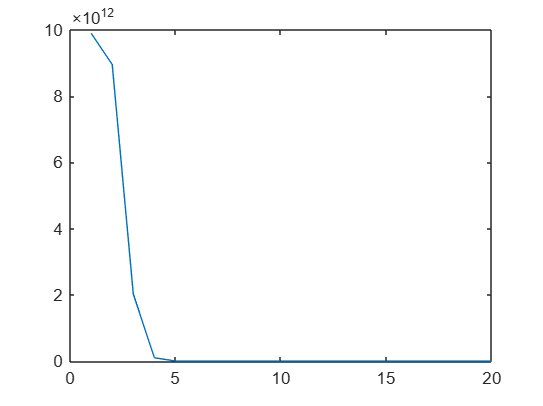

ns=1e-4*sum(sum(n.*[zeros(Nout,1);ones(Nw1,1);zeros(Nin,1);ones(Nw2,1);zeros(Nout,1)]));
nn=1e-6*n./a;
for x=1:1:20
        Occ_x=log(1+exp((mu-D(x))./kT));
        Ed_x=P(:,x)*Occ_x.*P(:,x);
        N_x=2*n0*Ed_x;
        density(x)=1e-4*sum(sum(N_x.*[ones(Np,1)])); 
end
    figure(2)
    plot(density);

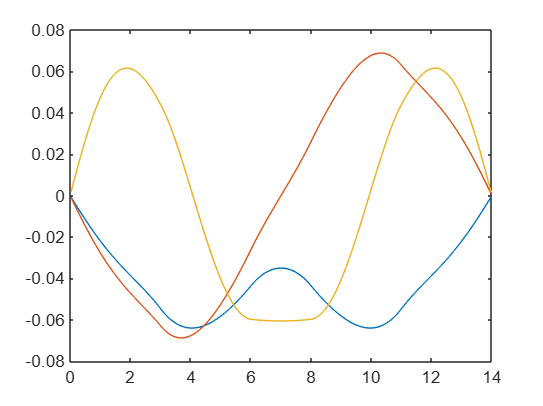

figure(3)
plot(XX,P(:,1),XX,P(:,2),XX,P(:,3))